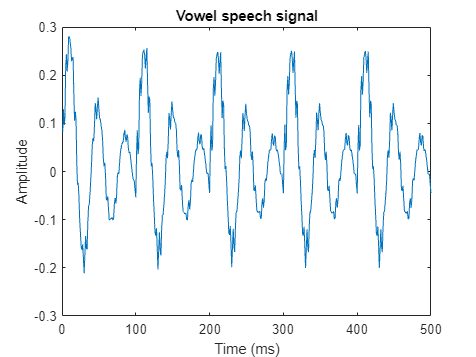

%{
    Problem 1

    a) Compute the short term autocorrelation given by equations(6.29) i.e  R_n[k] =(x[m]w[n − m])(x[m + k]w[n − k − m]) for summing over m = −∞ to ∞.
    (Hint:  Use the fact that the autocorrelation is a real function of k and that the window is symmetric.)
    and equation(6.35) i.e R_n[k] = (x[n + m]w[m])(x[n + m + k]w[k + m]) for summing over m = 0 to L-1-k. 
    Perform correlation in MATLAB using xcorr function for a Hamming window of length 50ms using 500 samples in the mid part of the data for lags m = 0, 1, 2, …, 100.

%}


% Matlab code generating vowel speech signal using audioread function from vowels_100Hz.wav files, the files are in the same folder as the code
% and plotting the signal and its spectrum
[vowel_100Hz,fs] = audioread('vowels_100Hz.wav');
vowel_100Hz = vowel_100Hz(1:500);
figure(1)
plot(vowel_100Hz)
title('Vowel speech signal')
xlabel('Time (ms)')
ylabel('Amplitude')

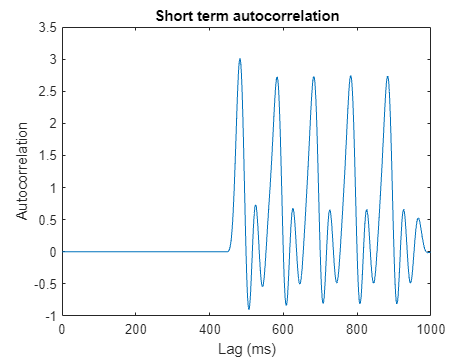


% set parameters
L = 50; % window length in ms
N = 500; % number of samples in the mid part of the data
w = hamming(L);% Hamming window

% compute the short term autocorrelation using matlab function xcorr
R_n = xcorr(vowel_100Hz,w,N-1,'none'); % autocorrelation for lags m = 0, 1, 2, …, 100

% plot the autocorrelation for lags m = 0, 1, 2, …, 100.
figure(2)
plot(R_n)
title('Short term autocorrelation')
xlabel('Lag (ms)')
ylabel('Autocorrelation')

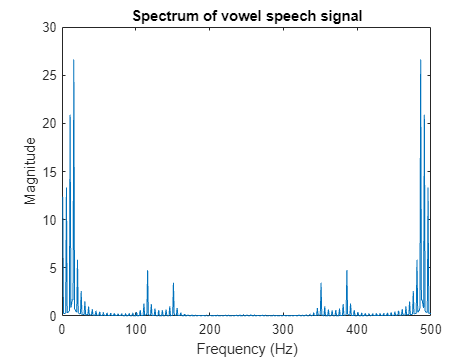


%{
    b) Compute the N = 500 point magnitude spectrum (use MATLAB fft function) of the
waveform based on a Hamming window and short-term DFT

%}

% computing the spectrum of the signal using fft function and plotting it N=500 points
vowel_100Hz_fft = fft(vowel_100Hz,N); 
vowel_100Hz_fft = abs(vowel_100Hz_fft); % magnitude spectrum
figure(2)
plot(abs(fft(vowel_100Hz)))
title('Spectrum of vowel speech signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

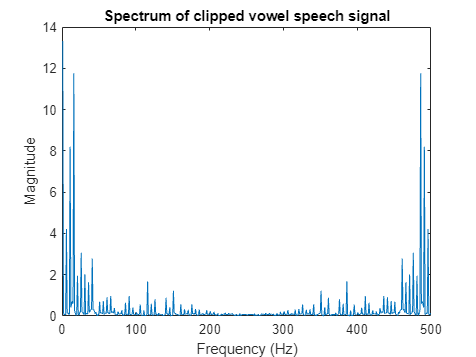

%{
    c) Repeat steps (a) and (b) after center clipping the waveform with clipping level set to 30% of the maximum signal
amplitude

%}

% center clipping the waveform with clipping level set to 30% of the maximum signal amplitude
vowel_100Hz_clipped = vowel_100Hz;
vowel_100Hz_clipped(vowel_100Hz_clipped > 0.3*max(vowel_100Hz_clipped)) = 0.3*max(vowel_100Hz_clipped);
vowel_100Hz_clipped(vowel_100Hz_clipped < -0.3*max(vowel_100Hz_clipped)) = -0.3*max(vowel_100Hz_clipped);

% computing the spectrum of the clipped signal using fft function and plotting it N=500 points
vowel_100Hz_clipped_fft = fft(vowel_100Hz_clipped,N);
vowel_100Hz_clipped_fft = abs(vowel_100Hz_clipped_fft); % magnitude spectrum
figure(3)
plot(abs(fft(vowel_100Hz_clipped)))
title('Spectrum of clipped vowel speech signal')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

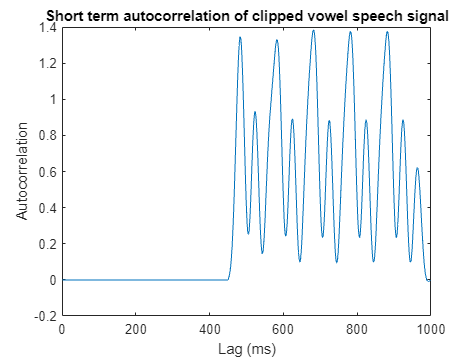


% computing the short term autocorrelation using matlab function xcorr
R_n_clipped = xcorr(vowel_100Hz_clipped,w,N-1,'none'); % autocorrelation for lags m = 0, 1, 2, …, 100

% plot the autocorrelation for lags m = 0, 1, 2, …, 100.
figure(4)
plot(R_n_clipped)
title('Short term autocorrelation of clipped vowel speech signal')
xlabel('Lag (ms)')
ylabel('Autocorrelation')

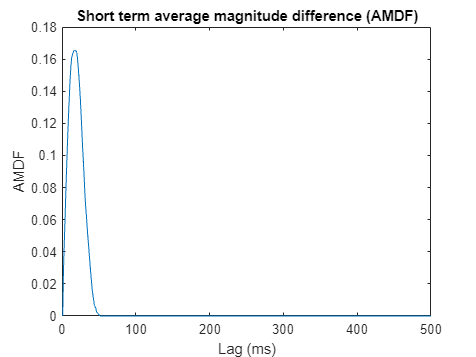

% computing the short-term average magnitude difference (AMDF) using the same window type, length, and data frame in Problem 1(a)
AMDF = zeros(1,N);
for k = 0:N-1
    for m = 0:L-1-k
        AMDF(k+1) = AMDF(k+1) + abs(vowel_100Hz(m+1) - vowel_100Hz(m+1+k));
    end
end
AMDF = AMDF/L;

% plot the AMDF for lags m = 0, 1, 2, …, 100.
figure(5)
plot(AMDF)
title('Short term average magnitude difference (AMDF)')
xlabel('Lag (ms)')
ylabel('AMDF')

%{
    b) Estimate the pitch and make conclusion as to the effect of center clipping on the pitch estimation.

%}

% computing the pitch using the autocorrelation function
[~,pitch] = max(R_n)

pitch = 482

pitch = pitch - 1; % pitch in ms

% computing the pitch using the autocorrelation function of the clipped signal
[~,pitch_clipped] = max(R_n_clipped)

pitch_clipped = 682

pitch_clipped = pitch_clipped - 1; % pitch in ms

% computing the pitch using the AMDF function
[~,pitch_AMDF] = min(AMDF)

pitch_AMDF = 1

pitch_AMDF = pitch_AMDF - 1; % pitch in ms



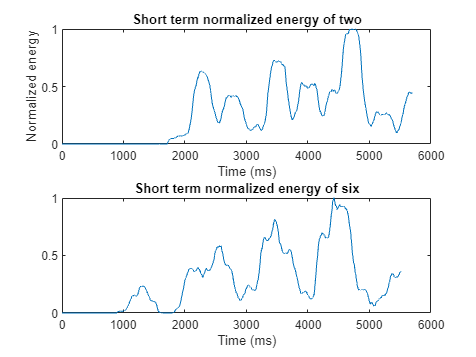

% Matlab code generating vowel speech signal using audioread function from two.wav and six.wav files, the files are in the same folder as the code
% and plotting the signal and its spectrum using subplot
[two,fs1] = audioread('two.wav');
[six, fs2] = audioread('six.wav');

% using fs to compute the length of the signal in ms
two_length = length(two)/fs1*1000;
six_length = length(six)/fs2*1000;

% computing the short term energy using the boxcar window of length N = 300 (30 ms) with no overlap
N = 300; % length of the window in ms
two_energy = zeros(1,two_length-N);
six_energy = zeros(1,six_length-N);
for k = 1:two_length-N
    two_energy(k) = sum(two(k:k+N-1).^2);
end
for k = 1:six_length-N
    six_energy(k) = sum(six(k:k+N-1).^2);
end

% normalizing the energy
two_energy = two_energy/max(two_energy);
six_energy = six_energy/max(six_energy);

% plotting the energy of the two words
figure(6)
subplot(2,1,1)
plot(two_energy)
title('Short term normalized energy of two')
xlabel('Time (ms)')
ylabel('Normalized energy')
subplot(2,1,2)
plot(six_energy)
title('Short term normalized energy of six')
xlabel('Time (ms)')

% computing the spctrum of the two words using fft function and plotting it N=300 points
two_fft = fft(two,N);
two_fft = abs(two_fft); % magnitude spectrum
six_fft = fft(six,N);
six_fft = abs(six_fft); % magnitude spectrum

% plotting the spectrum of the two words
figure(7)
subplot(2,1,1)
plot(abs(fft(two)))
title('Spectrum of two')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
subplot(2,1,2)
plot(abs(fft(six)))
title('Spectrum of six')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

